# Výpočet zážehového motoru

clc;
clear all;
close all;

### Vstupní data

a=not(false); % input('Zadejte  1 pro standardní vstupy, 0 pro zadání hodnot:');
if a
%-------------------------Standardní vstupní data---------------------
%----------Parametry motoru------
V=2.5;                    % [l] Zdvihový objem
N=4;                      % [-] Počet válců
n=3000;                   % [1/min] otáčky motoru
r_c=8.6;                  % [-] Kompresní poměr
X=1.025;                  % [-] Poměr vrtání zdvih S/B
eta_m=0.86;               % [-] Mechanická účinnost
EGR=4;                    % [-] Vnitřní recirkulace spalin EGR

%---------Fuel Inputs/Combustion Efficiency----
x=8;                      % [-] Počet atomů uhlíku
y=18;                     % [-] Počet atomů vodíku
AF=15;                    % [-] Poměr vzduch palivo
eta_conv=1;               % [-] Účinnost spalování

%--Vlastnosti pracovních tekutin---------------- 
%--průměrná hodnota mezi dvěma exterémy (SOC & EOCombeating)
K=1.35;                   % [-] Poissonova kontanta
R=0.287;                  % [kJ/kg.K] Měrná plynová kontanta vzduchu
C_v=0.821;                % [kJ/kg.K] Měrna tepelná kapacit při konstantním objemu vzduchu 
C_p=R+C_v;                % [kJ/kg.K] Měrna tepelná kapacit při konstantním tlaku vzduchu 

%---------Parametry atmosferického vzduchu------------
P_0=100;                  % [kPa] Barometrický tlak
T_0=60;                   % [°C] Teplota vzduch ve válci na začátku komprese
row_0=P_0/(R*(293.15));   % [kg/m^3] Hustota vzduchu v referenčních podmínkách 
%-----------------------------------------------------------------
else
%-----------------------Libovolná vstupní data------------------
%----------Vstupní parametry motoru------
V=input('Zdvihový objem motoru [litr] : ');
N=input('Počet válců motoru : ');
n=input('Otáčky motoru [1/min]: ');
r_c=input('Kompresní poměr: ');
X=input('Import Stroke-to-Bore Ratio S/B: ');
eta_m=input('Mechanická účinnost:');
EGR=input('Procento interní recyrkulace EGR: % ');
%---------Parametry paliva/účinnosti----
disp('---------------CxHy Složení paliva------------ ');
x=input('Počet atomů uhlíku v palivu: ');
y=input('Počet atomů vodíku: ');
b=x/y;
AF_s=(34.56*(b+4))/(12.011+(1.008*b));     % Stoichiometrický poměr Vzduch/Palivo (Heywood (5-3))
Z= ['Pro dokonalé spalování musí být poměr vzduch-palivo ',num2str(AF_s),' or Higher'];
disp(Z)
AF=input('Poměr Vzduch/Palivo : ');
eta_conv=input('Účinnost spalování : ');
%---------Atmosferické podmínky------------
P_0=input('Barometrický tlak [kPa] : ');
T_0=input('Teplota válce na začátku komprese [°C] : ');
R=input('Plynová konstanta [kJ/kg.K] : ');
K=input('Poissonova konstakta, adiabatický koeficient vzduchu : ');
C_v=input('Měrná tepelná kapacita při konstantním tlaku vzduchu [kJ/kg] : ');
C_p=R+C_v;                % [kJ/kg.K] Měrna tepelná kapacit při konstantním tlaku vzduchu 
row_0=P_0/(R*(293.15));   % [kg/m^3] Hustota vzduchu v referenčních podmínkách 
end

### Výpočet

%--------Palivo přívod tepla & účinnost spalování----
M_C=(x*12)/((x*12)+(y));                           % Hmotnostní podíl uhlíku v palivu
M_H=(y*0.68)/((x*12)+(y));                         % Hmotnostní podíl vodíku v palivu
FHV=((14600*M_C)+(62000*M_H))*2.326;               % [kJ/kg] Výhřevnost paliva [Dulong s formula]
b=x/y;
AF_s=(34.56*(b+4))/(12.011+(1.008*b));             % Stechiometrický poměr Vzduch/Palivo (Heywood (5-3))
lambda=AF/AF_s;
Th_Air=lambda*100;                                 % Teoretický podíl vyduchu
EAP=Th_Air-100;                                    % Procento přebytku vzduchu

if lambda >= 1                                    
    eta_ch=1;
else
    eta_ch=(1.3773*lambda)-0.3773;                 %Schmidt (1996)
end
eta_c=eta_conv*eta_ch;                             %Pischinger (1989)

#### Pro jeden válec

V_d=(V/N)/1000;                 % [m^3] Zdvihový objem
V_c=V_d/(r_c-1);                % [m^3] Kompresní objem
B=((4*V_d/pi*X)^(1/3))*100;     % [cm] Vrtání
S=B*X;                          % [cm] Zdvit
A_p=(pi*(B^2))/4 ;              % [cm^2] Plocha pístu

Stav 1 (Začátek komprese) 

T_1=(T_0)+273;                  % [K] Temprature of Gas Mixture in Cylinder at State 1 (Deg K)
P_1=P_0;                        % [kPa] Pressure of Gas Mixture in Cylinder at State 1   (kPa)
V_1=V_d+V_c;                    % [m^3] Volume of Gas Mixture in Cylinder at State 1     (Cubic Meter)

%----Výpočet hmotnosti plynů------
M_m=(P_1*V_1)/(R*T_1);   % [kg] Mass of Gas Mixture in Cylinder (kg)

% hmotnost uvnitř válce pak zůstane stejná pro celý cyklus

M_a=(AF/(AF+1))*((100-EGR)/100)*M_m;    % [kg] Mass of Air in Cylinder                         (kg)
M_f=(1/(AF+1))*((100-EGR)/100)*M_m;     % [kg] Mass of Fuel in Cylinder                        (kg)
M_ex=(EGR/100)*M_m;                     % [kg] Mass of Exhaust Residual in Cylinder at SOC     (kg)
   

Stav 2 (Začátek spalování)

T_2=(T_1)*((r_c)^(K-1));                % [K] Temprature of Gas Mixture in Cylinder at State 2 (K)
P_2=(P_1)*((r_c)^K);                    % [kPa] Pressure of Gas Mixture in Cylinder at State 2   (kPa)
V_2=V_1/r_c;                            %Volume of Gas Mixture in Cylinder at State 2     (Cubic Meter)

State 3 (Konec spalování)

T_3=((FHV*eta_c)/((AF+1)*C_v))+T_2;     % [K] Temprature of Gas Mixture in Cylinder at State 3 (Deg K)
P_3=(P_2/T_2)*T_3;                      % [kPa] Pressure of Gas Mixture in Cylinder at State 3   (kPa)
V_3=V_2;                                %Volume of Gas Mixture in Cylinder at State 3     (Cubic Meter)

Tlakový poměr (změna tlaku během spalování)

Alpha=P_3/P_2;                          % [kPa] Pressure Increase During Contant-Volume Combustion 


State 4 (Konec expanze)

T_4=T_3*((1/r_c)^(K-1));                % [K] Temprature of Gas Mixture in Cylinder at State 4 (Deg K)
P_4=P_3*((1/r_c)^K);                    % [kPa] Pressure of Gas Mixture in Cylinder at State 4   (kPa)
V_4=(M_m*R*T_4)/P_4;                    %Volume of Gas Mixture in Cylinder at State 4     (Cubic Meter)


Stav 5 

T_5=T_1;                                % [K] Temprature of Gas Mixture in Cylinder at State 5 (Deg K)
P_5=P_1;                                % [kPa] Pressure of Gas Mixture in Cylinder at State 5   (kPa)
V_5=V_1;                                %Volume of Gas Mixture in Cylinder at State 5     (Cubic Meter)

Stav 6 

T_6=T_0;                                %Temprature of Gas Mixture in Cylinder at State 6 (Deg K)
P_6=P_0;                                % [kPa] Pressure of Gas Mixture in Cylinder at State 6   (kPa)
V_6=V_2;                                %Volume of Gas Mixture in Cylinder at State 6     (Cubic Meter)

#### Děje

Děj 1-2 (Komprese)

Q_12=0;
W_12=M_m*C_v*(T_1-T_2);     % [kJ]

Děj 2-3 (Spalování)

Q_23=M_f*FHV*eta_c;         % [kJ]
W_23=0;

3-4 Process (Expression)

Q_34=0;
W_34=M_m*C_v*(T_3-T_4);     %  [kJ]

4-5 Process  (Exhaust)

Q_45=M_m*C_v*(T_5-T_4);     % [kJ] 
W_45=0;

### Overal Engine Performance

U_p=2*S*n*(1/6000);                         % [m/s] Střední pístová rychlost
W_i=W_12+W_34;                              % [kJ] Čistá indikovaná práce pro jeden válec během jednoho cyklu
Q_in=M_f*FHV*eta_c;                         % [kJ] Přidáno teplo pro jeden válec během jednoho cyklu
eta_t=W_i/Q_in;                             % [-] Termická účinnost
imep=W_i/(V_d);                             % [kPa] Střední Indikovaný tlak
bmep=imep*eta_m;                            % [kPa] Střední efektivní tlak
W_idat=W_i*N*(n/(60*2));                    % [kW] Indikovaný výkon při {n} 1/min
W_b=eta_m*W_i;                              % [kJ] Čistá efektivní práce pro jeden válec během jednoho cyklu
W_bdat=W_b*N*(n/(60*2));                    % [kW] Efektivní výkon při  {n} 1/min
Taw=(W_bdat/(2*pi*(n/60)))*1000;            % [N.m] Točivý moment                                               
W_fdat=W_idat-W_bdat;                       % [kW] Ztrátový třecí výkon
BSP=W_bdat/A_p;                             % [kW/ccm] Efektivní měrný výkon
OPD=W_bdat/V;                               % [kW/l] Měrný výkon
M_fdat=M_f*(n/60)*(1/2)*N;                  % [kg/s] Rychlost vstřikování paliva do všech válců během jednoho cyklu
bsfc=(M_fdat/W_bdat)*3600000;               % [g/kW-h] Měrná efektivní spotřeba paliva
eta_v=M_a/(row_0*V_d);                      % [-] Objemová účinnost

### Zobrazení výsledků

disp('---------------------Palivo & Vlastnosti spalování------------------------ ');

---------------------Palivo & Vlastnosti spalování------------------------ 


F=[x y];
disp('     C     H')

     C     H


disp(F)

     8    18



A = ['Skutečný poměr Vzduch/Palivo je : ',num2str(AF)];
disp(A)  

Skutečný poměr Vzduch/Palivo je : 15


Z = ['Stoichiometrický poměr Vzduch/Palivo je : ',num2str(AF_s)];
disp(Z)

Stoichiometrický poměr Vzduch/Palivo je : 12.3284


T=['Teoretické procento vzduchu je : ',num2str(Th_Air)];
disp(T)

Teoretické procento vzduchu je : 121.6699


E=['Procento přebytečného vzduchu je: ',num2str(EAP)];
disp(E)

Procento přebytečného vzduchu je: 21.6699


Eff=['Celková účinnost spalování : ',num2str(eta_c)];
disp(Eff)

Celková účinnost spalování : 1


HV=['Výhřevnost paliva : ',num2str(FHV), ' kJ/kg'];
disp(HV)

Výhřevnost paliva : 44081.3726 kJ/kg


disp('                                                                   ');

disp('-------------------Vlastnosti pracovního bodu cyklu-------------------------- ');

-------------------Vlastnosti pracovního bodu cyklu-------------------------- 


disp('                                                                   ');

aa=['Maximálni teplova v cyklu : ',num2str(T_3-273.15), ' °C'];
disp(aa)

Maximálni teplova v cyklu : 3789.78 °C


ab=['Maximální tlak v cyklu je : ',num2str(P_3), ' kPa'];
disp(ab)

Maximální tlak v cyklu je : 10492.8521 kPa


disp('                                                                   ');

disp('---------------------------Celkové výkonnové parametry motoru --------------- ');

---------------------------Celkové výkonnové parametry motoru --------------- 


disp('                                                                   ');

a15=['Střední pístová rychlost je : ',num2str(U_p),' m/s'];
disp(a15)

Střední pístová rychlost je : 9.577 m/s


a1=['Termická účinnost je : ',num2str(eta_t)];
disp(a1)

Termická účinnost je : 0.55115


a2=['Střední indikovaný tlak imep je : ',num2str(imep), ' kPa'];
disp(a2)

Střední indikovaný tlak imep je : 1725.9747 kPa


a3 = ['Střední efektivní tlak je : ',num2str(bmep), ' kPa'];
disp(a3)  

Střední efektivní tlak je : 1484.3382 kPa


a5 = ['Indikovaný výkon při ',num2str(n),' 1/min je : ',num2str(W_idat), ' kW'];
disp(a5)

Indikovaný výkon při 3000 1/min je : 107.8734 kW


a6 = ['Efektivní výkon při ',num2str(n),' 1/min je : ',num2str(W_bdat), ' kW'];
disp(a6)

Efektivní výkon při 3000 1/min je : 92.7711 kW


a8=['Ztrátový třecí výkon : ',num2str(W_fdat), ' kW'];
disp(a8)  

Ztrátový třecí výkon : 15.1023 kW


a7 = ['Točivý moment při ',num2str(n),' 1/min : ',num2str(Taw), ' N-m'];
disp(a7)    

Točivý moment při 3000 1/min : 295.2997 N-m


a9=['Měrná efektivní spotřeba bsfc : ',num2str(bsfc), ' g/kW-h'];
disp(a9)

Měrná efektivní spotřeba bsfc : 172.2978 g/kW-h


a12 = ['Objemová účinnost : ',num2str(eta_v)];
disp(a12)

Objemová účinnost : 0.89655


a10 = ['Měrný výkon OPD : ',num2str(OPD), ' kW/Litr'];
disp(a10)

Měrný výkon OPD : 37.1085 kW/Litr


a11 = ['Specifický efektivní výkon BSP je: ',num2str(BSP), ' kW/cm^2'];
disp(a11)

Specifický efektivní výkon BSP je: 1.353 kW/cm^2


a13 = ['Poměr zvýšení tlaku během spalování s konstantním objemem je : ',num2str(Alpha)];
disp(a13)

Poměr zvýšení tlaku během spalování s konstantním objemem je : 5.7454


### Kreslení grafů

p-V diagram

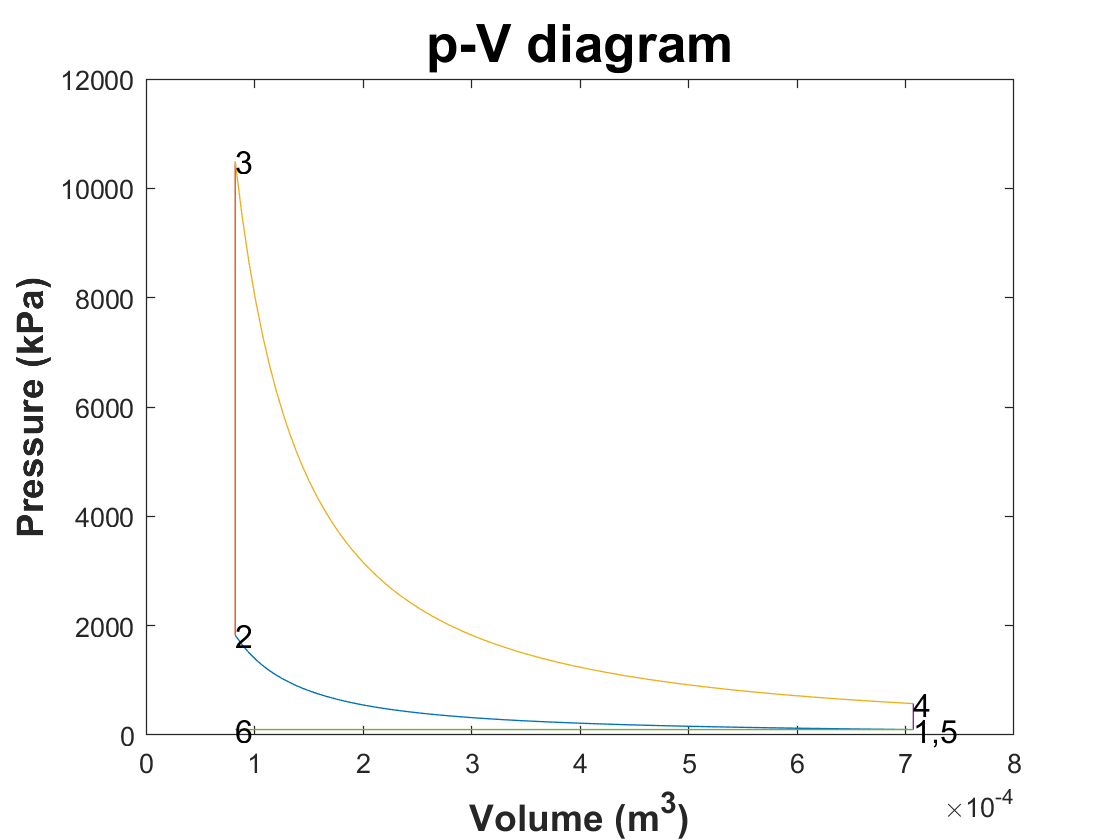

%---Plot 1-2 Process (Compression)
V_12=linspace(V_1,V_2,100);
P_12=((V_1./V_12).^K)*P_1;
plot(V_12,P_12);
title('p-V diagram','FontSize', 20 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Volume (m^3)','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Pressure (kPa)','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
%---Kreslí děj 2-3 (Spalování)
V_23=[V_2 V_3];
P_23=[P_2 P_3];
plot(V_23,P_23);
%---Kreslí děj 3-4 (Expanze)
V_34=linspace(V_3,V_4,100);
P_34=((V_3./V_34).^K)*P_3;
plot(V_34,P_34);
%---Kreslí děj 4-1 (Výfuk)
V_41=[V_4 V_1];
P_41=[P_4 P_1];
plot(V_41,P_41);
%---Kreslí děj 5-6 (Sání výfuk)
V_56=[V_5 V_6];
P_56=[P_5 P_6];
plot(V_56,P_56);

hold off

text(V_1,P_1, '1,5' ,  'FontSize' ,12)
text(V_2,P_2, '2' ,  'FontSize' ,12)
text(V_3,P_3, '3' ,  'FontSize' ,12)
text(V_4,P_4, '4' ,  'FontSize' ,12)
text(V_6,P_6, '6' ,  'FontSize' ,12)

figure;

**T-S Diagram**

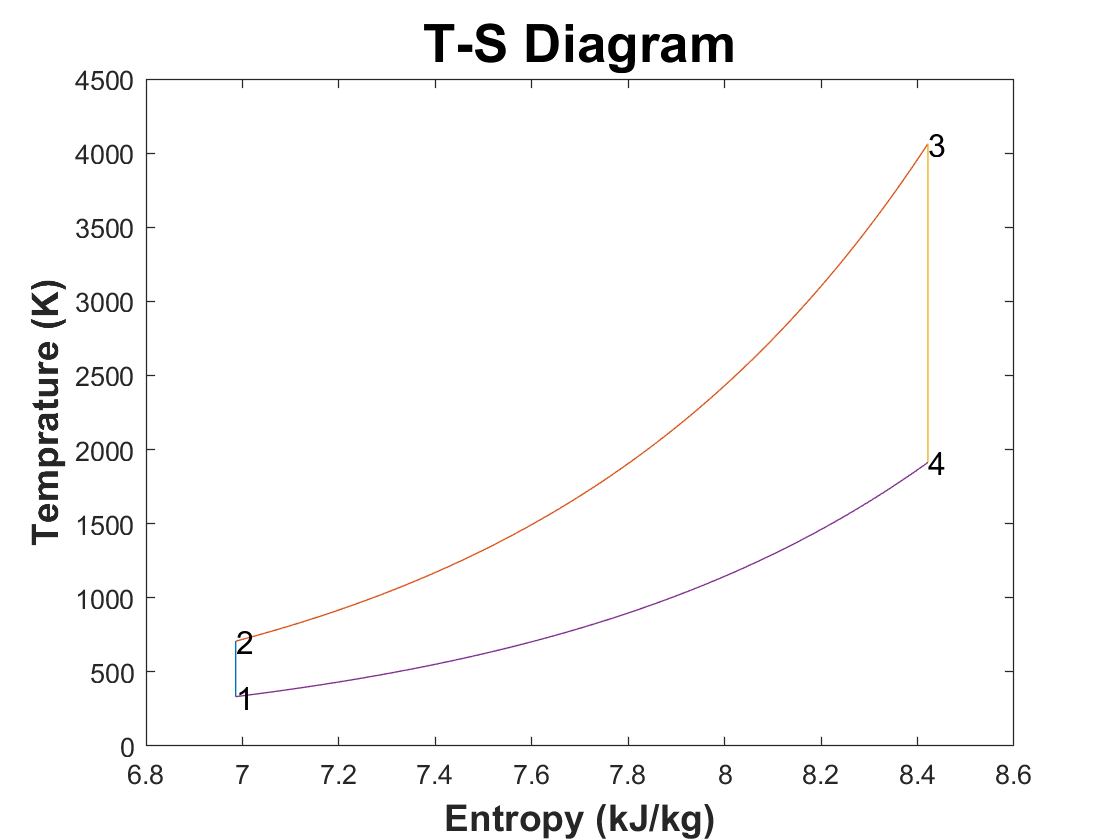

%Refference State:   ( Table A/12SI Van Wylen Ed.4 )
Pref=P_0;            % 0.1 [MPa]
Tref=298.15;         % 25 [°C]
Sref=6.86305;        % [kJ/kgK]
%---Kreslí děj  1-2 (Komprese)
S_1=Sref+(C_p*log((T_0+273.15)/Tref));      %( Rovnice  10-31 Van Wylen Ed.4 )
S_2=S_1;
S_12=[S_1 S_2];
T_12=[T_1 T_2];
plot(S_12,T_12);
title('T-S Diagram','FontSize', 20 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Entropie [kJ/kg]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Teplota [K]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
%---Kreslí děj  2-3 (Spalování)
T_23=linspace(T_2,T_3,100);
S_23=S_2+(C_v*log(T_23/T_2));           %( Rovnice 10-33 Van Wylen Ed.4 )
S_3=S_2+(C_v*log(T_3/T_2));
plot(S_23,T_23);
%---Kreslí děj  3-4 (Expanze)
S_4=S_3;
S_34=[S_3 S_4];
T_34=[T_3 T_4];
plot(S_34,T_34);
%---Kreslí děj 4-1 (Výfuk)
T_41=linspace(T_4,T_1,100);
S_41=S_4+(C_v*log(T_41/T_4));           %( Rovnice 10-33 Van Wylen Ed.4 )
plot(S_41,T_41);

hold off

text(S_1,T_1, '1' ,  'FontSize' ,12)
text(S_2,T_2, '2' ,  'FontSize' ,12)
text(S_3,T_3, '3' ,  'FontSize' ,12)
text(S_4,T_4, '4' ,  'FontSize' ,12)